# BME 2740 Interactive Lecture 17

# By: Dr . Asad Mirza

# Adapted From: Dr. Ilmar Tamames

Make sure you have installed Symbolic Math Toolbox™ functions in order to properly run the code in this lesson.

## Methods for Nonlinear Equations

Linear functions can **all** be analyzed with linear algebra and can be solved or optimized. Even some non-linear functions can be represented as abstract vector spaces and solved or optimized with linear algebra.

Unfortunately, most functions in the world are nonlinear and cannot be handled by linear algebra:


$$y\left(x_1 ,x_2 \right)=\frac{x_1 -x_2 }{x_1^2 +x_2^2 +2}$$


When local linearization is not appropriate, we need new tools.

#### Finding Zeros

Zeros tell us so much about functions and systems, this is often the first place to start looking to understand them if you cannot solve the problem directly.

Often, we wish to find the zero-crossings of a function called “roots”. Roots may correspond to optimal points on the function.

#### Root-Finding Methods

At what input value is the function output zero?


$$x_r :\mathrm{\ }f{\left(x_r \right)}=0$$


These *inputs* are called roots or *zeros* of$\mathrm{\ }f{\left(x_r \right)}$ and frequently occur in BME and many fields.

**Goal: Find the value of x that makes f(x)=0.**

#### Newton’s Method

The most famous root finding method, is Newton's method, derived from the Taylor Series. Requires $f\left(x\right)$ and $f^{\prime } {\left(x\right)}\;$to be continuous and differentiable but it is **very fast**.

Let  $x\mathrm{\ }=x_0 +\textrm{∆}x$ and $a=x_0$,


$$f{\left(x\right)}=f{\left(x_0 \right)}+f^{\prime } {\left(x_0 \right)}∆x+\ldots$$


If $x$ is the root then:


$$0=f{\left(x_0 \right)}+f^{\prime } {\left(x_0 \right)}\left(x-x_0 \right)+\ldots$$



$$0\approx f{\left(x_0 \right)}+f^{\prime } {\left(x_0 \right)}x-f^{\prime } {\left(x_0 \right)}x_0$$



$$x=\frac{f^{\prime } {\left(x_0 \right)}x_0 -f{\left(x_0 \right)}}{f^{\prime } {\left(x_0 \right)}}=x_0 -\frac{f{\left(x_0 \right)}}{f^{\prime } {\left(x_0 \right)}}$$



$$x=x_0 -\frac{f{\left(x_0 \right)}}{f^{\prime } {\left(x_0 \right)}}$$


This method is summarized per point:


$$x_{i+1} =x_i -\frac{f{\left(x_i \right)}}{f^{\prime } {\left(x_i \right)}}$$


#### Newton’s Method - Alternate Derivation

We an use the point slope form to figure out the formula.


$$y-y_0 =m\left(x-x_0 \right)$$


Here: $x_0$ is our initial guess for the zero. $y_0$ is our function at $x_0$ or$f\left(x_0 \right)$, m is our slope or derivative at $x_0$ or $f^{\prime } \left(x_0 \right)$

We assume $y$ is 0 since it is the root we are aiming for.

Solving for x


$$\begin{array}{l}
0-y_0 =m\left(x-x_0 \right)\\
-\frac{y_0 }{m}=x-x_0 \\
x-x_0 =-\frac{y_0 }{m}\\
x=x_{0-} \frac{y_0 }{m}\\
x_{i+1} =x_i -\frac{f{\left(x_i \right)}}{f^{\prime } {\left(x_i \right)}}
\end{array}$$


General Steps:

- Select an initial guess, $x_0$, ideally it's based upon a best guess from a plotted figure, the value already close to the suspected zero.

- Follow the tangent line at $f{\left(x_i \right)}\;$until it crosses $y=0$.

- Let $x_{i+1}$ be the tangent line zero crossing computed at $f{\left(x_i \right)}\;\ldotp$

- Repeat 2-3. until convergence.

OR 

1. Choose an initial guess (x0�).

- Look at the graph and choose a value close to the suspected root.

2. Draw a tangent line.

- Find the slope using the derivative, f′(x0�).

3. Find where the tangent line crosses the x-axis.

- This gives your next guess, x1

4. Repeat the process.

- Use the new guess to calculate another tangent line and another estimate.

5. Stop when the answer converges.

- Continue until the guesses become very close to the actual root.

Note that this procedure requires the evaluation of $f^{\prime } {\left(x\right)}$ and$f{\left(x\right)}$.

With enough iterations it **should** narrow down to the actual zero for the function. 

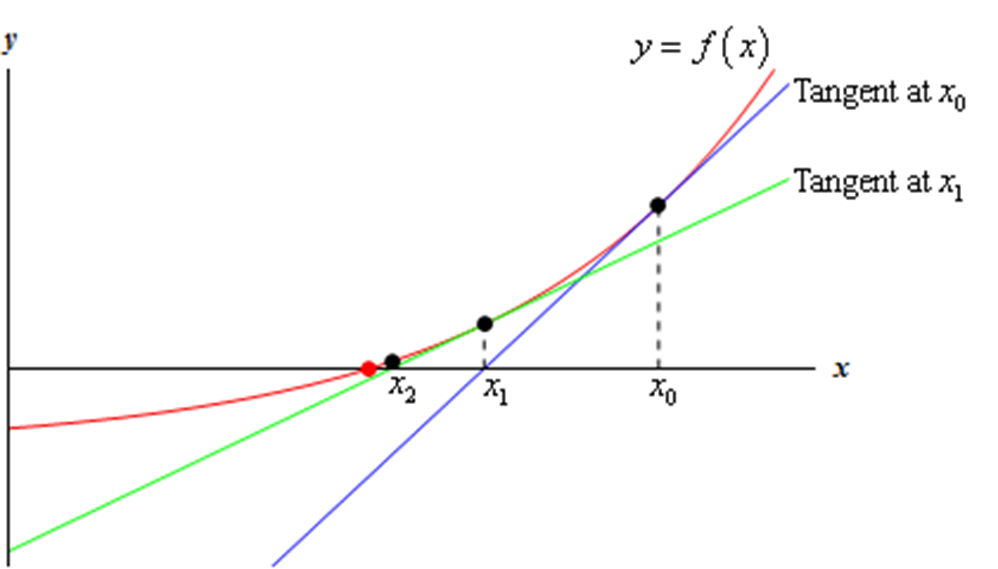

## Example 1: Newton-Raphson (NR) Root Finding

As an employee of the FDA, it is your job to ensure that biomedical products are safe before their use in humans. You are given the specifications for an artificial heart valve and must decide if it is suitable for use as a valve replacement. The elastic modulus of the valve indicates that the valve can withstand up to 110 mmHg pressure in 0.12 seconds before failure. Given the governing equation for pressure in the heart during the cardiac cycle, $P\left(t\right)=1300t-3000t^2$, where P is pressure and t is time during heartbeat, determine if this valve can be approved. 

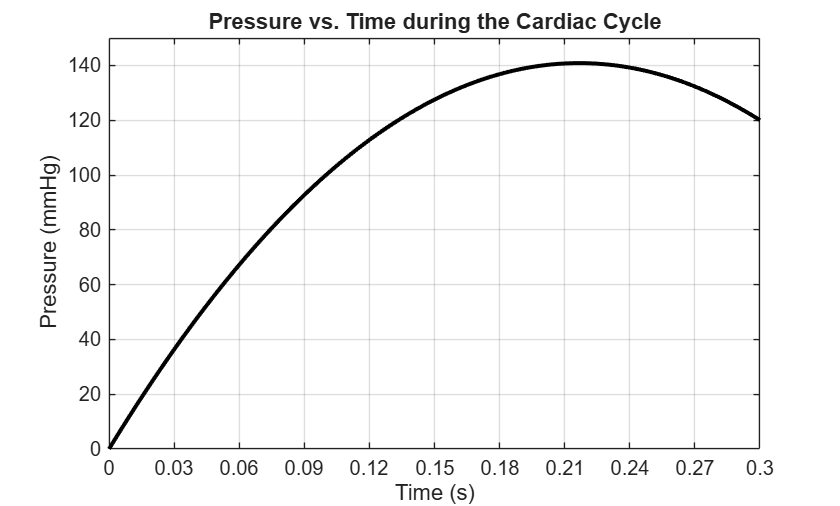

% EX 1)
% FDA Evaluation of Artificial Heart Valve
% This script evaluates whether an artificial heart valve can withstand 
% the pressure changes in the heart during the cardiac cycle.

clear; clc; 

% STEP 1: Define the pressure function P(t) during the cardiac cycle
    % This equation calculates the pressure at any given time (t).
P = @(t) -3000*t.^2 + 1300*t; 

% STEP 2: Define the time range for evaluation
    % Starts at 0 seconds, ends at 0.3 seconds, and increases by 0.001 seconds.
t = 0:0.001:0.3; 

% STEP 3: Create a figure and plot pressure versus time
% Plots time on the x-axis and calculated pressure on the y-axis.
figure;
plot(t, P(t), '-k', 'LineWidth', 2);
xlabel('Time (s)'); % Label x-axis
ylabel('Pressure (mmHg)'); % Label y-axis
title('Pressure vs. Time during the Cardiac Cycle'); % Title
% STEP 4: Set axis ticks for better readability
    % Y-axis increases by 20 mmHg, from 0 to 140.
yticks(0:20:140);
    % X-axis increases by 0.03 seconds, from 0 to 0.3.
xticks(0:0.03:0.3);
grid on; 


% STEP 5: Valve failure criteria
max_pressure = 110; % mmHg
failure_time = 0.12; % seconds
% Compare the pressure at 0.12 seconds to the maximum allowed pressure.
% If the pressure is greater than 110 mmHg, the valve fails.
% Otherwise, the valve is considered suitable.

% Check if the valve withstands the pressure
if P(failure_time) > max_pressure
    disp('The valve is NOT suitable for use. It fails under normal heart conditions.');
else
    disp('The valve is suitable for use. It can withstand normal heart pressures.');
end

The valve is NOT suitable for use. It fails under normal heart conditions.


Hint: Use NR to determine when P(x) is at least 110mmHg, and if this occurs between t=0 and t=0.12 seconds, reject the valve. The maximum tolerance is 0.01.


$$P\left(t\right)=\;110=1300t-3000t^2$$



$$0=1300t-3000t^2 -110$$


- STEP 1: Define the pressure function and its derivative.

- STEP 2: Convert symbolic functions to numeric functions.

- STEP 3: Plot the shifted pressure function.

- STEP 4: Perform Newton's Method manually.

- STEP 5: Check if the manual calculation converged.

- STEP 6: Perform the automated Newton-Raphson method.

- STEP 7: Plot the function again.

- STEP 8: Run the automated Newton-Raphson loop.

- STEP 9: Check for convergence.

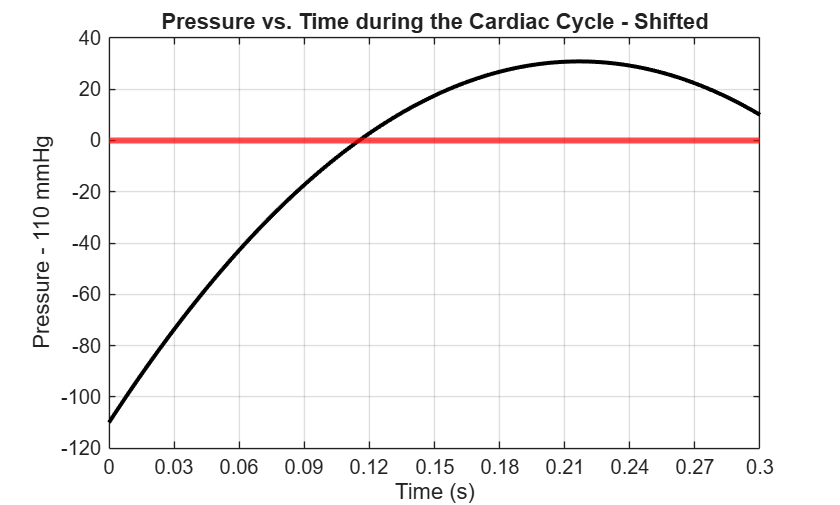

% FDA Evaluation of Artificial Heart Valve using Newton-Raphson Method
% This script determines if an artificial heart valve can withstand 
% normal heart pressures by finding when P(t) reaches 110 mmHg.

clear; clc; % Clear workspace and command window

% STEP 1 Define the pressure function and its derivative
syms t;
P(t) = -3000*t.^2 + 1300*t - 110; % Pressure equation shifted for 110 mmHg threshold
df(t) = diff(P, t); % First derivative of f(t)

% STEP 2 Convert symbolic functions to numeric functions
f = matlabFunction(P);
df = matlabFunction(df);

% STEP 3 Plot P(t) - 110 to visualize root
t_vals = 0:0.001:0.3; % Time values from 0 to 0.3 seconds
figure;
plot(t_vals, f(t_vals), '-k', 'LineWidth', 2);
hold on;
xlabel('Time (s)');
ylabel('Pressure - 110 mmHg');
title('Pressure vs. Time during the Cardiac Cycle - Shifted');
xticks(0:0.03:0.3);
yline(0, 'r', 'LineWidth', 3); % Red reference line at P = 110 mmHg
grid on;

%% STEP 4 Step-by-Step Newton's Method (Manual Calculation)
x0 = 0.01; % Initial guess
tol = 0.01; % Maximum tolerance
fprintf('Iteration   x_n      f(x_n)      f''(x_n)     x_(n+1)\n');

Iteration   x_n      f(x_n)      f'(x_n)     x_(n+1)



% 1st Iteration
f_x0 = f(x0);
df_x0 = df(x0);
x1 = x0 - f_x0 / df_x0;
fprintf('%2d        %.4f   %.4f   %.4f   %.4f\n', 1, x0, f_x0, df_x0, x1);

 1        0.0100   -97.3000   1240.0000   0.0885


% 2nd Iteration
f_x1 = f(x1);
df_x1 = df(x1);
x2 = x1 - f_x1 / df_x1;
fprintf('%2d        %.4f   %.4f   %.4f   %.4f\n', 2, x1, f_x1, df_x1, x2);

 2        0.0885   -18.4716   769.1935   0.1125


% 3rd Iteration
f_x2 = f(x2);
df_x2 = df(x2);
x3 = x2 - f_x2 / df_x2;
fprintf('%2d        %.4f   %.4f   %.4f   %.4f\n', 3, x2, f_x2, df_x2, x3);

 3        0.1125   -1.7300   625.1084   0.1152


% 4th Iteration
f_x3 = f(x3);
df_x3 = df(x3);
x4 = x3 - f_x3 / df_x3;
fprintf('%2d        %.4f   %.4f   %.4f   %.4f\n', 4, x3, f_x3, df_x3, x4);

 4        0.1152   -0.0230   608.5029   0.1153


% STEP 5 Final Check
xr_manual = x4;
if abs(f(xr_manual)) < tol
    fprintf('Converged manually at x = %.4f\n', xr_manual);
else
    fprintf('Did not converge manually within 4 iterations.\n');
end

Converged manually at x = 0.1153


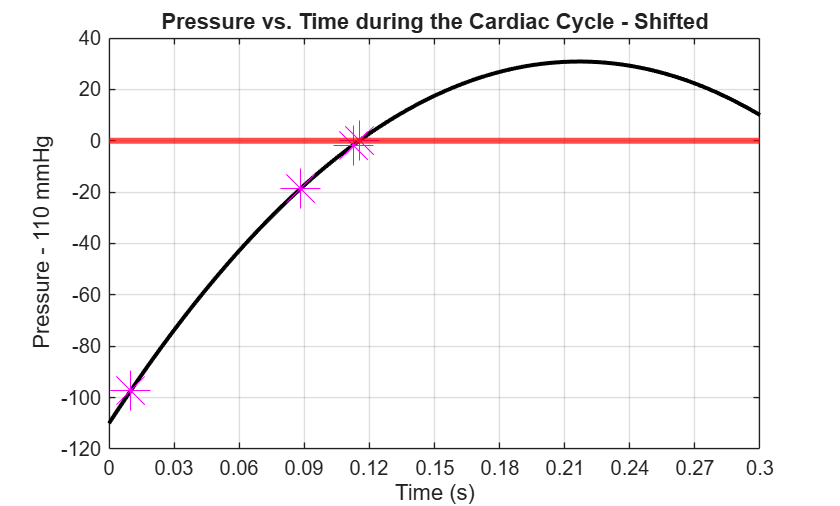

--------------------------------


Iter   xr       f(xr)


1     0.0885     -18.4716
2     0.1125     -1.7300
3     0.1152     -0.0230
4     0.1153     -0.0000


%% STEP 6 Automated Newton-Raphson Method Loop
xr = x0; % Initialize xr with initial guess
max_iter = 20; % Maximum iterations


% STEP 7
figure;
plot(t_vals, f(t_vals), '-k', 'LineWidth', 2);
hold on;
xlabel('Time (s)');
ylabel('Pressure - 110 mmHg');
title('Pressure vs. Time during the Cardiac Cycle - Shifted');
xticks(0:0.03:0.3);
yline(0, 'r', 'LineWidth', 3); % Red reference line at P = 110 mmHg
grid on;
for ii = 1:max_iter
    xr_new = xr - f(xr) / df(xr); % Newton-Raphson update
    plot(xr,f(xr),'m*','MarkerSize',20) % Plot estimate
    if ii==1
        fprintf('--------------------------------\n');
        fprintf('Iter   xr       f(xr)\n');
    end
    fprintf('%1.0f     %1.4f     %1.4f\n', ii, xr_new, f(xr_new)); % Display iteration results
      % Check for convergence
    if abs(f(xr_new)) < tol
        xr = xr_new;
        break;
    end
    xr = xr_new; % Update value for next iteration
end


% STEP 8 Determine if the valve should be rejected
if xr >= 0 && xr <= 0.12
    disp('Valve fails the safety test: Pressure reaches 110 mmHg within 0.12 seconds.');
else
    disp('Valve passes the safety test: Pressure does not reach 110 mmHg within 0.12 seconds.');
end

Valve fails the safety test: Pressure reaches 110 mmHg within 0.12 seconds.


TIP: [Syms](https://www.mathworks.com/help/symbolic/syms.html)

Newton’s method is extremely fast and stable. Although, there are a few unusual situations where the algorithm fails to converge

a) Here we are unlucky enough that the slope found at $x_1$ points us **away** from the zero and back towards $x_0$. This loop would essentially repeat forever unless we change $x_0$ or we get lucky enough for our $x_1$ to fall to the left of the initial guess.

b) Here we are unlucky enough that the choice for $x_0$ results in a feedback loop where $x_1$'s slope leads back to exactly $x_0$. Only solution is to pick a better $x_0$.

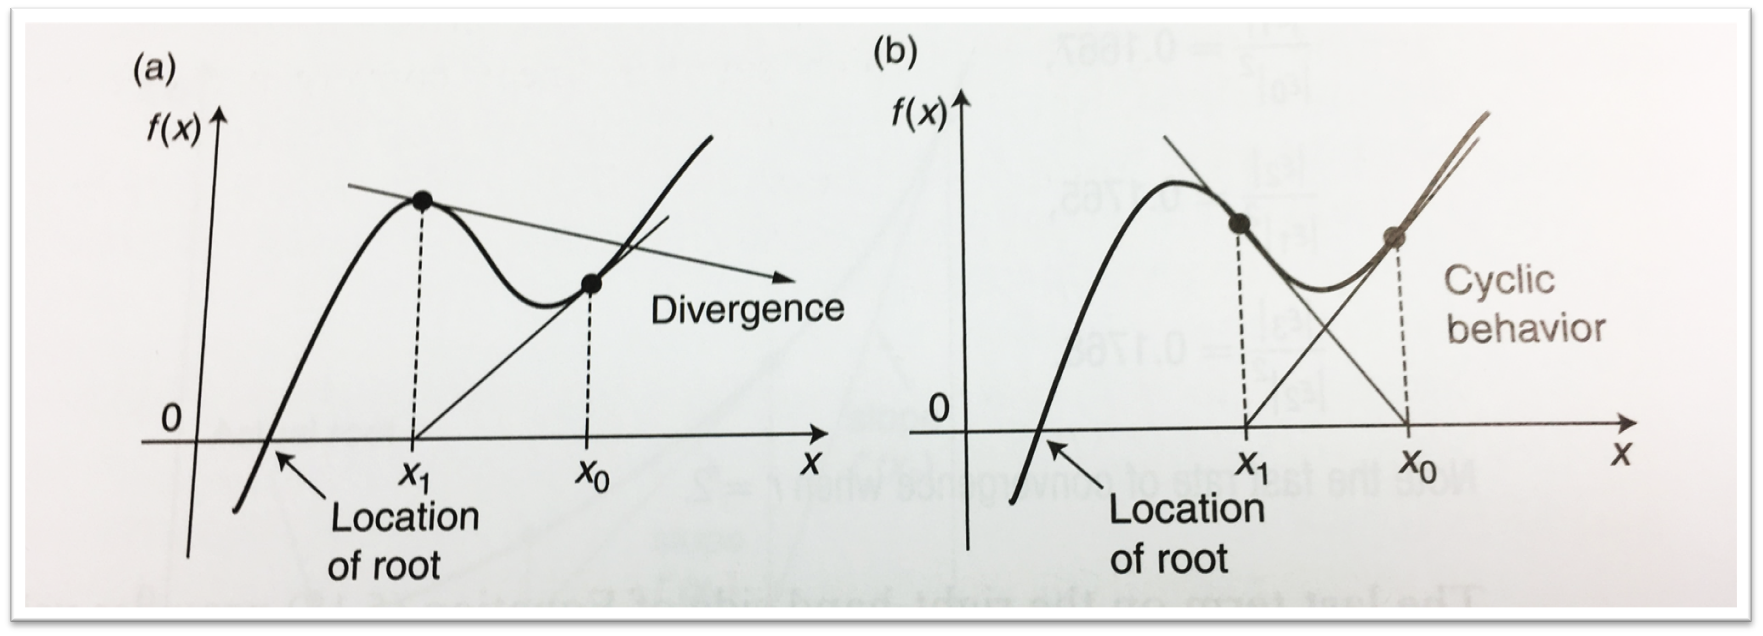

#### Example 2

Use the Newton’s method to find the root of $f{\left(x\right)}=x^2 -22x-230$, to within 0.01 using an initial guess of  $x_r =-9$ . Plot from -14 to -5.

 a) Find the second root of the equation using Newton’s method.

•*Extra Challenge*: Under what conditions will Newton’s method return the correct answer in exactly zero or one iteration?

Iter   xr       f(xr)


 0     -9.0000     49.0000


 1     -7.7750     1.5006
 2     -7.7350     0.0016


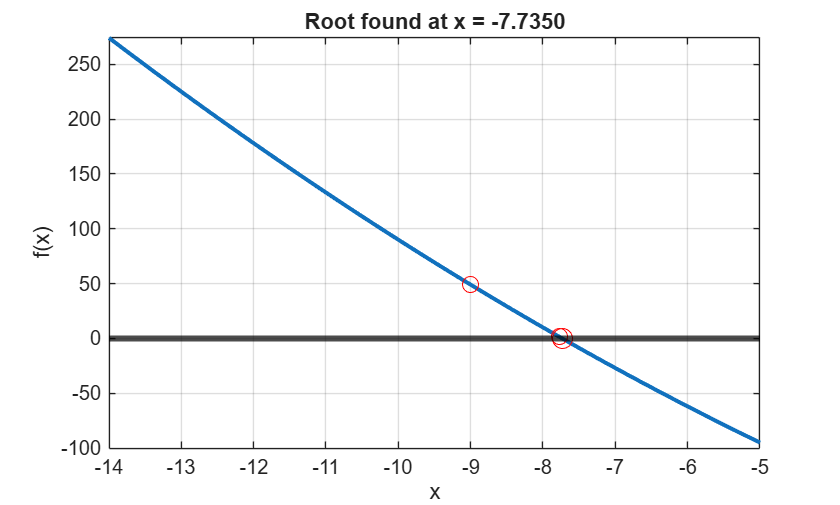

% Newton's Method for Root-Finding
clear; clc;




% STEP 1: Define the function and its derivative
syms x;

P(x) = x^2 - 22*x - 230; % Given equation
dPx(x) = diff(P, x);      % Find the derivative of P(x)
% diff(P,x) means differentiate with respect to x

% Convert symbolic functions to numeric functions
P = matlabFunction(P);    % Allows MATLAB to evaluate P at numerical values
dPx = matlabFunction(dPx); % Allows MATLAB to evaluate the derivative numerically



% STEP 2: Set up visualization parameters
xspan = [-14 -5]; % X-span for plotting (given in the question)

% Plot the function
figure; 
fplot(P, xspan, 'linewidth', 2); % Plots the function over the x-span
hold on; 
xlabel('x'); ylabel('f(x)'); 
yline(0, 'LineWidth', 3, 'Color', 'k'); % Draws horizontal line at y=0
grid on; 



%% STEP 3: Newton's Method for First Root (Initial Guess: x0 = -9)

xr = -9;       % Initial guess (given in the question)
itr = 0;       % Iteration counter starts at zero
maxTol = 0.01; % Desired tolerance (accuracy)



% STEP 4: Newton's Method loop
% Keep repeating while the function value is greater than tolerance
while abs(P(xr)) > maxTol && itr < 20

    % Plot the current point on the graph
    plot(xr, P(xr), 'ro', 'MarkerSize', 8);

    if itr==0
        fprintf('Iter   xr       f(xr)\n');
        % Display the column headings ONLY during the first iteration

        % Display current iteration, current guess, and function value
        fprintf('%2d     %1.4f     %1.4f\n', itr, xr, P(xr));

        itr=itr+1; % Increase iteration counter
    end

    % STEP 5: Apply Newton's Method formula
    % New guess = Current guess - Function value / Derivative value
    xr = xr - P(xr) / dPx(xr);

    % Display the updated guess and its function value
    fprintf('%2d     %1.4f     %1.4f\n', itr, xr, P(xr));

    % STEP 6: Increase iteration counter by 1
    itr = itr + 1;
end


% Final root plot and result
plot(xr, P(xr), 'ro', 'MarkerSize', 10);
title(sprintf('Root found at x = %.4f', xr));
hold off;

Iteration   xr         f(xr)


   0     800.0000       5.9758


   1     801.9956      -5.1943
   2     800.7625       2.2521
   3     801.1203      -0.0950
   4     801.1061       0.0000


TIP: [fplot](https://www.mathworks.com/help/symbolic/fplot.html)

#### Example 3:

Find a root of $f{\left(x\right)}=ln{\left(x\right)}*sin{\left(x\right)}$ to within a tolerance of 0.001 using an initial guess of  $x_r =800$. Plot from 795 to 805.

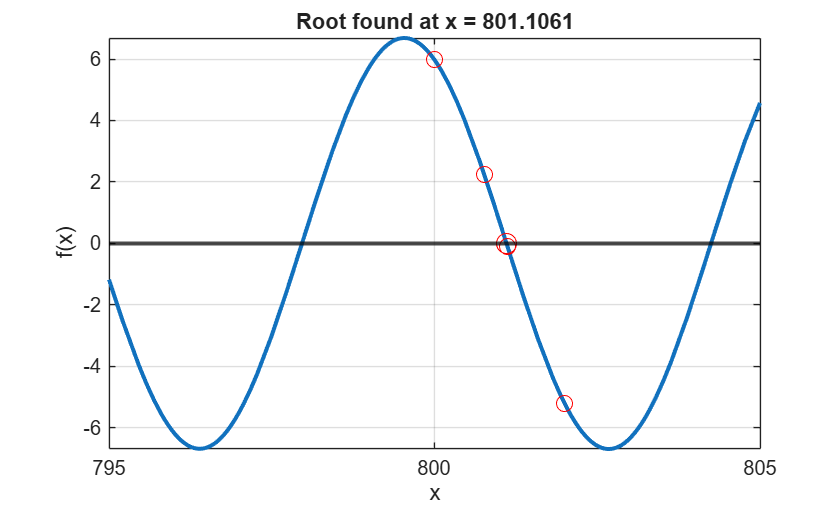

% Newton's Method to find root of f(x) = log(x) * sin(x)
clear; clc;



% STEP 1 Setup variables

xr = 800; % Initial guess
maxTol = 0.001; % Tolerance for convergence
tspan = [790 805]; % Range for plotting



% STEP 2  Define the function and its derivative
syms x; % allows MATLAB to work with symbolic equations  <<<< DO NOT FORGET
P(x) = log(x) * sin(x); % FUCNTION GIVEN
dPx(x) = diff(P, x);



% STEP 2 Convert symbolic functions to numeric functions

Example 1 - Root of f(u) near u = 0.1: u = 0.11529


P = matlabFunction(P);
dPx = matlabFunction(dPx);


 
Search for an interval around 0.1 containing a sign change:
 Func-count    a          f(a)             b          f(b)        Procedure
    1             0.1           -10           0.1           -10   initial interval
    3       0.0971716      -12.0039      0.102828       -8.0441   search
    5           0.096       -12.848         0.104        -7.248   search
    7       0.0943431      -14.0558      0.105657       -6.1362   search
    9           0.092       -15.792         0.108        -4.592   search
   11       0.0886863      -18.3036      0.111314       -2.4644   search
   13           0.084       -21.968         0.116         0.432   search
 
Search for a zero in the interval [0.084, 0.116]:
 Func-count    x          f(x)             Procedure
   13           0.116         0.432        initial
   14        0.115383     0.0581031        interpolation
   15        0.115287  -5.12651e-05        interpolation
   16        0.115287   2.41741e-08        interpolation
   17        0

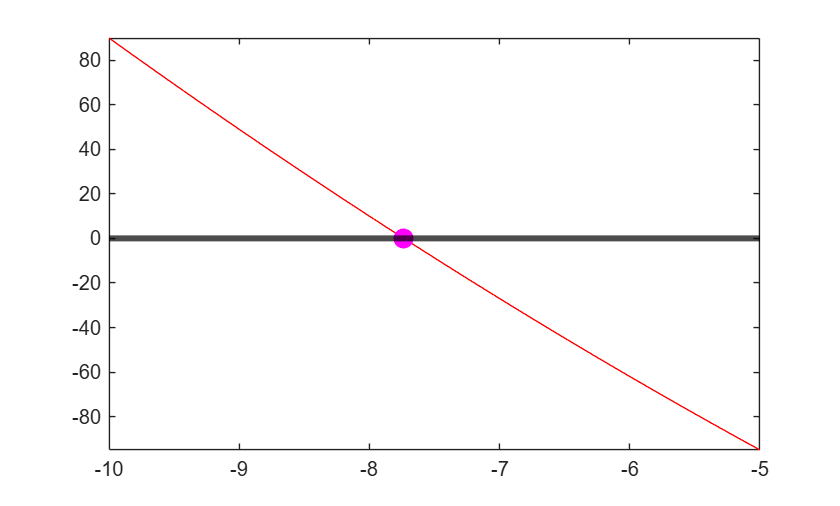

Example 2 - Root of f(u) near u = -9: u = -7.735




% STEP 3 Plot to visualize initial point
figure;
fplot(P, tspan, 'linewidth', 2);
% ^ fplot graphs your function over the interval tspan.  <<<<<<<<
xlabel('x'); 
ylabel('f(x)');
yline(0, 'LineWidth', 2, 'Color', 'k');
% yline(0) shows where the root is located (where f(x) = 0). <<<<<<<<
grid on;
hold on;


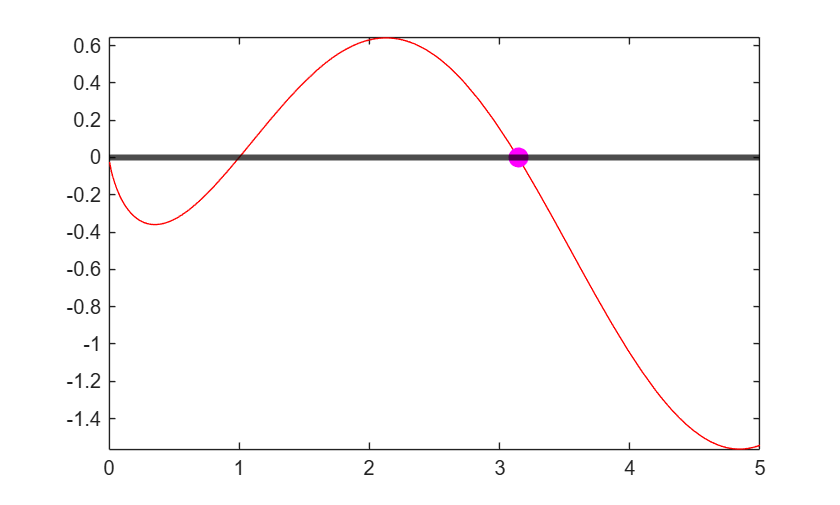

% STEP 4 Run Newton's Method
itr = 0; % counts how many times Newton's formula is repeated.

while abs(P(xr)) > maxTol && itr < 20 % Limit to 20 iterations to avoid infinite loop
    % Plot the current point on the graph
    plot(xr, P(xr), 'ro', 'MarkerSize', 8);
    if itr==0
        fprintf('Iteration   xr         f(xr)\n');
        fprintf('%4d     %8.4f   %10.4f\n', itr, xr, P(xr));
        itr=itr+1;
    end

    % Update xr using Newton's Method formula

Example 3 - Root of f(x) near x = 800: x = 3.1416


    xr = xr - P(xr) / dPx(xr);
    %  ^ MOST IMPORTANT LINE: NEWTON'S METHOD FORMULA.
    %  ^ New estimate = Old estimate - f(old x)/f'(old x).
    %  ^ Remember: P(xr) is the function and dPx(xr) is its derivative.
    %  ^ This formula improves the estimate of the root each iteration.

    %The r in xr, P(xr), and dPx(xr) stands for root estimate (or the current estimated root).
    % It's used to show that we're evaluating the function at our current guess of the root, 
    % rather than at just any x-value.

    % Display current iteration, xr, and f(xr)
    fprintf('%4d     %8.4f   %10.4f\n', itr, xr, P(xr));
    % Increment iteration counter
    itr = itr + 1;
end


% STEP 5 Final root plot and result
plot(xr, P(xr), 'ro', 'MarkerSize', 10);
title(sprintf('Root found at x = %.4f', xr));
% Zoom in on graph
xlim([795 805])
hold off;

#### Fzero

Like with many things in MATLAB there is a function for finding roots, this one is called fzero and previously we used it to solve our Backwards Euler Method code. Give it a function, $f$, and an initial guess, $x_0$, and it will run through the same Newton steps we did above automatically and report to you the root, if it exists.

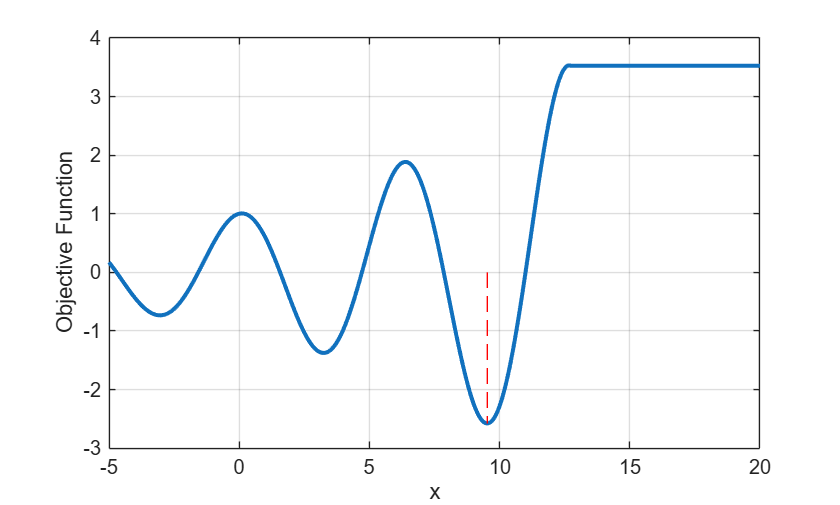

% Clear workspace
clear; clc;

% Example 1: Root finding for a quadratic equation
% Define the function f(u) = -3000u^2 + 1300u - 110
f = @(u) -3000*u.^2 + 1300*u - 110;

% Run fzero to find the root, starting from an initial guess of u = 0.1
% This will find the value of u for which f(u) = 0
root = fzero(f, 0.1);
disp(['Example 1 - Root of f(u) near u = 0.1: u = ', num2str(root)]);
% Optional: Add descriptive options to display iteration details
options = optimset('Display', 'iter');
fzero(f, 0.1, options);


% Example 2: Root finding for another function
% Define the function f(u) = u^2 - 22u - 230
f = @(u) u.^2 - 22*u - 230;

% Run fzero to find the root, starting from an initial guess of u = -9
root = fzero(f, -9);
figure
fplot(f,'r')
hold on
plot(root,f(root),'m.','MarkerSize',30)
yline(0,'k','LineWidth',3)
xlim([-10 -5])
disp(['Example 2 - Root of f(u) near u = -9: u = ', num2str(root)]);

% Example 3: Root finding for a trigonometric-logarithmic function
% Define the function f(x) = log(x) * sin(x)
f = @(x) log(x) .* sin(x);
root = fzero(f, 4);
figure
fplot(f,'r')
hold on
plot(root,f(root),'m.','MarkerSize',30)
yline(0,'k','LineWidth',3)
xlim([0 5])
disp(['Example 3 - Root of f(x) near x = 800: x = ', num2str(root)]);

TIP: [Fzero](https://www.mathworks.com/help/matlab/ref/fzero.html)

#### Optimization

- Getting the most out of something.

- Fitting the data in “the best possible way” in some sense. Meaning fitting it in such a way to minimize $r^2$ while also eliminating patterns in the residuals.

- Obtaining a model that is most representative of the system.

- The “thing” we want to optimize is called the **Objective Function**

For linear algebra and root finding techniques, optimizations would always find the best result (LinAlg), or at least if you didn’t find the result you could check how well you did (root finding).

In nonlinear optimization, in general, it is impossible to tell if the optimization has produced the **best** possible solution or just the best **closest** solution.

Root finding provided us with robust ways to find zeroes of a function of interest. We now are looking to find the peaks or valleys of our objective function, which represent places in our objective function that are the in some way higher/lower than the surrounding areas.

#### Step function

Quick refresher. Before moving on, recall an important function, the unit step function, or Heaviside function. Typical engineering function for applications in which the function is either off or on.


$$\left(t<a\right)={\left\{\begin{array}{c}
0\mathrm{\ }\mathrm{\ }\mathrm{\ }if\mathrm{\ }t<a\\
1\mathrm{\ }\mathrm{\ }\mathrm{\ }if\mathrm{\ }t\ge a
\end{array}\right)}$$


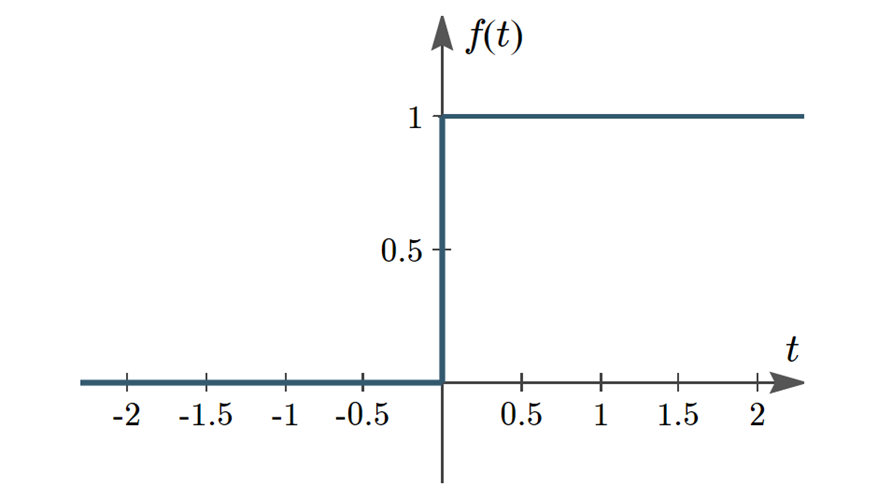

Examples:

- Drug Administration - The Heaviside function models the sudden injection of a drug into the bloodstream, where the concentration jumps to an initial value and then decays over time.

- Muscle Activation - In musculoskeletal modeling, the step function simulates sudden muscle activation or contractions.

- Pulsatile Valve Behavior - In cardiovascular models, a step function can represent valve behavior being open or closed as well as sudden changes in arterial pressure.

- Electrical Circuit Switches - Step inputs simulate real-life actions, like powering a circuit or disconnecting a load, making it possible to analyze transient responses of capacitors, inductors, or complex circuits.

- Mechanical Systems- In mechanical engineering, a step function represents forces that are suddenly applied to structures or materials. This is used in analyzing vibrations, shock responses, and impact forces on mechanical structures, helping engineers predict stress and deformation over time.

#### **Example 4: **

Find the minimum values between 5 and 10 for the function:


$$f{\left(x\right)}=\cos \left(x\right)e^{0\ldotp 1x} \left(x<c\right)+\left(\cos \left(c\right)*e^{0\ldotp 1c} \right)\left(x\ge c\right)$$



$$f\left(x\right)\left\lbrace \begin{array}{ll}
\cos \left(x\right)e^{0\ldotp 1x}  & x<c\\
\left(\cos \left(c\right)e^{0\ldotp 1c} \right) & x\ge c
\end{array}\right.$$


With $c=4\ldotp 05\pi$ and tolerance of 0.01.

clear,clc,close all
% Define constants and parameters
c = 4.05 * pi;
xspan = [5, 10];  % Interval to search for minimum

% Define the objective function
fx = @(x) cos(x) .* exp(x / 10) .* (1 - heaviside(x - c)) + ...
          cos(c) * exp(c / 10) .* heaviside(x - c);
% Plot the function over a wider range to observe behavior
x = linspace(-5, 20, 500);
figure
plot(x, fx(x), 'linewidth', 2);
ylabel('Objective Function');
xlabel('x');
grid on;
hold on;
% From solution in next code block, this is what we want to find.
line([9.52906 9.52906],[0,fx(9.52906)] ,Color = 'red',LineStyle = '--');

Ite   X0       X1       DFx      D2Fx


 1   8.5000  10.4681  -2.0090   1.0208
 2  10.4681   9.2556   2.3181   1.9117
 3   9.2556   9.5389  -0.6737   2.3774
 4   9.5389   9.5245   0.0378   2.6122
 5   9.5245   9.5244   0.0001   2.6050


Converged at x = 9.5244 after 5 iterations.


Red line here represents the "global minimum" the other minimums would be called "local minimums". 

#### Unconstrained Single-Variable Optimization

Start with the simplest case, Newton’s method


$$f{\left(x\right)}\approx f{\left(x_0 \right)}\;+\;f^{{\left(1\right)}} {\left(x_0 \right)}{\left(x-x_0 \right)}\;+\;\frac{f^{\left(2\right)} {\left(x_0 \right)}}{2}{{\left(x-x_0 \right)}}^2 \;+\;\ldotp \ldotp \ldotp$$


At the maximum (or min) of the function, $f{\left(x^* \right)}$, the derivative is zero:


$$\begin{array}{l}
\frac{d}{dx}f{\left(x\right)}\;=f^{{\left(1\right)}} {\left(x_0 \right)}+2{\left(x-x_0 \right)}\frac{f^{\left(2\right)} {\left(x_0 \right)}}{2}\\
0=f^{{\left(1\right)}} {\left(x_0 \right)}+{\left(x-x_0 \right)}f^{\left(2\right)} {\left(x_0 \right)}\\
-\frac{f^{{\left(1\right)}} {\left(x_0 \right)}}{f^{\left(2\right)} {\left(x_0 \right)}}=x-x_0 \\
x_0 -\frac{f^{{\left(1\right)}} {\left(x_0 \right)}}{f^{\left(2\right)} {\left(x_0 \right)}}=x\\
x=x_0 -\frac{f^{\left(1\right)} {\left(x_0 \right)}}{f^{\left(2\right)} {\left(x_0 \right)}}
\end{array}$$


For it to work it must be twice differentiable near $x_0$ and the second derivative must be computable. We will be in trouble if $f^{\left(2\right)} {\left(x_0 \right)}$ approaches zero near $c$.


$$f\left(x\right)\left\lbrace \begin{array}{ll}
\cos \left(x\right)e^{0\ldotp 1x}  & x<c\\
\left(\cos \left(c\right)e^{0\ldotp 1c} \right) & x\ge c
\end{array}\right.$$


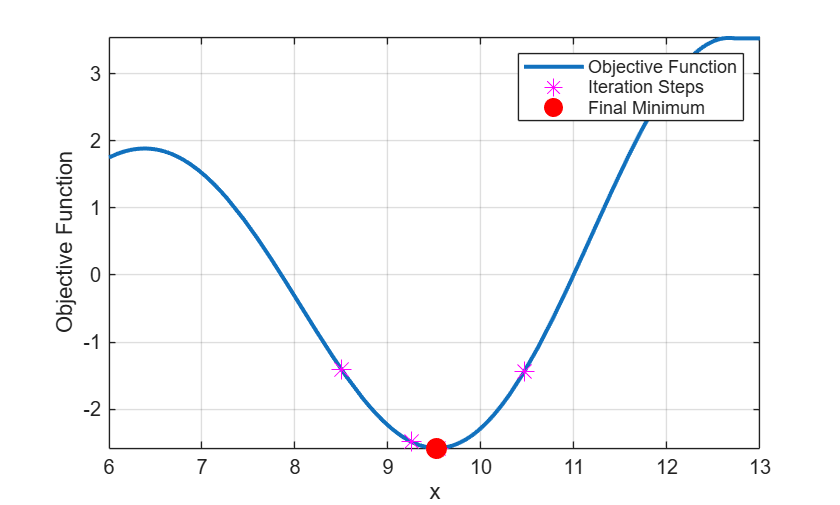

clear, clc, close all

% Setup coefficients
c = 4.05 * pi;

tspan = [5 20];
tolx = 0.001;

% Define the functions
syms x
P(x) = cos(x) .* exp(x / 10) .* (1 - heaviside(x - c)) + ...
          cos(c) * exp(c / 10) .* heaviside(x - c);
dPx(x) = diff(P, x);     % First derivative
d2fx(x) = diff(P, x, 2); % Second derivative

% Convert symbolic functions to numeric functions
dPx = matlabFunction(dPx);
d2fx = matlabFunction(d2fx);

% Plot the function over the specified range
fplot(P, tspan, 'linewidth', 2);
ylabel("Objective Function")
xlabel("x");
grid on;
hold on;

% Initialize variables for Newton's method
x0 = 8.5;
maxloops = 30;
for ii = 1:maxloops
    % Compute gradient and Hessian
    grad_val = dPx(x0);
    hess_val = d2fx(x0);

    % Compute next x using Newton's update
    x1 = x0 - grad_val / hess_val;

    % Plot current position on the function curve
    plot(x0, P(x0), 'm*', 'MarkerSize', 10);
    if ii==1
        % Run the optimization loop
        fprintf('Ite   X0       X1       DFx      D2Fx\n');
    end
    % Print iteration details
    fprintf('%2d %8.4f %8.4f %8.4f %8.4f\n', ii, x0, x1, grad_val, hess_val);

    % Check for convergence
    if abs(x1 - x0) <= tolx
        fprintf('Converged at x = %.4f after %d iterations.\n', x1, ii);
        break;
    end
    
    % Update x0 for the next iteration
    x0 = x1;
end

% Mark the final minimum found on the plot
plot(x1, P(x1), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
legend('Objective Function', 'Iteration Steps','','','','','Final Minimum');
hold off;
xlim([6 13])

Ite   X0      X1      DFx       D2Fx


 1   40.000   53.678 106067.865 -7754.429
 2   53.678   60.494 28089.118 -4121.437
 3   60.494   61.671 3656.329 -3107.032
 4   61.671   61.699   84.776 -2964.316
 5   61.699   61.699    0.048 -2960.948


Converged at x = 61.6991 after 5 iterations.


TIP: [heaviside](https://www.mathworks.com/help/symbolic/heaviside.html)

TIP: [Subs](https://www.mathworks.com/help/symbolic/subs.html)

Notice how the first derivative approaches zero.

We do not have an “absolute” termination criterion, i.e., we stop when the change in function evaluation slows to an acceptable level.

We could also stop when the change in derivative of the function evaluation nears zero.

#### Example 5: Optimization

You are the chief scientist at Bottom’s-Up Craft Brewing, and the brew master has asked you to increase the company’s profits by optimizing the fermentation process. You describe the process with the following model:


$$f{\left(Q\right)}=8000PMWa{\left(1-\frac{1}{1+\frac{kV}{Q}}\right)}-4000{{\left(8000\rho Q\right)}}^{0.6}$$


where Q is the flow-rate of materials to the fermenter and f(Q) is the gross from the process. Flow-rate can vary from 10 to 100 $m^3 /h$. How can we determine the best flow-rate of materials, $Q^*$, using these coefficients and a tolerance of 0.01?

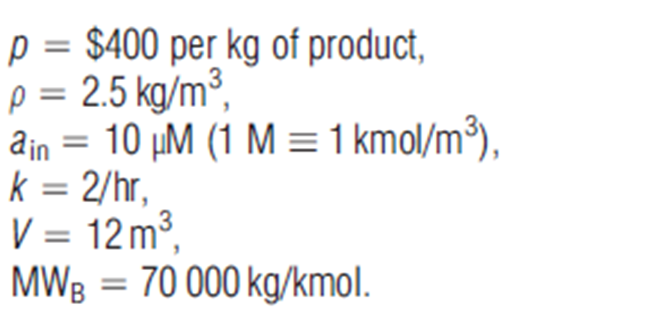

Hint: We are looking for the maximum value.

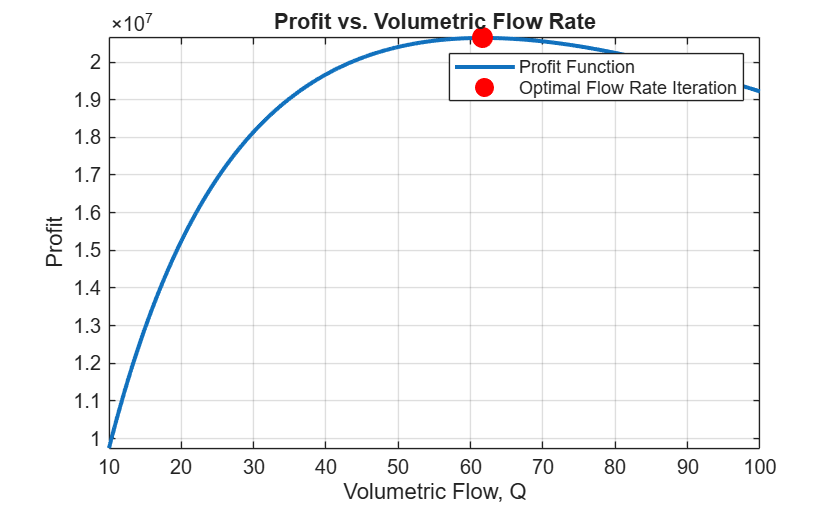

clear,clc,close all 

% Constants for the profit function

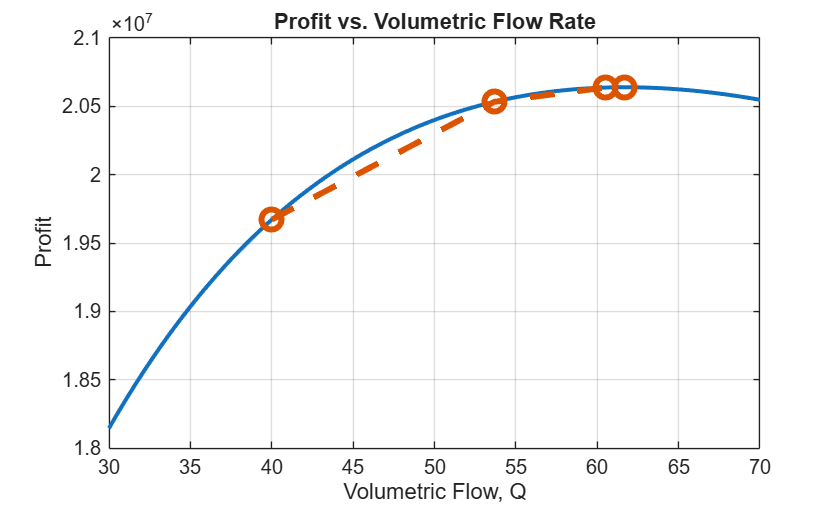

p = 400;         % Some constant related to profit
rho = 2.5;       % Density of material
a = 10e-6;       % Constant for the model
k = 2;           % Reaction rate constant
V = 12;          % Volume
MWB = 70e3;      % Molecular weight of B
tolx = 0.01;     % Tolerance for convergence
tspan = [10, 100]; % Range for Q (flow rate)

% Define the profit function and its derivatives
syms Q;

P(Q) = 8000 * p * MWB * Q * a * (1 - 1 / (1 + k * V / Q)) ...
       - 4000 * (8000 * rho * Q)^0.6;
dPx(Q) = diff(P, Q);       % First derivative
d2fx(Q) = diff(P, Q, 2);   % Second derivative
% Convert symbolic functions to numeric functions
dPx = matlabFunction(dPx);
d2fx = matlabFunction(d2fx);

% Plot the profit function over the range of Q
figure;
fplot(P, tspan, 'linewidth', 2);
xlabel('Volumetric Flow, Q');
ylabel('Profit');
title('Profit vs. Volumetric Flow Rate');
grid on;
hold on;

% Initial guess for Newton's Method
x0 = 40;
maxloops = 20;

% Run the optimization loop using Newton's Method
for ii = 1:maxloops
    
    % Evaluate derivatives at current point
    gradValue = dPx(x0);
    hessValue = d2fx(x0);

    % Update estimate using Newton's Method
    x1 = x0 - gradValue / hessValue;
    
    % Display iteration information
    if ii == 1
        fprintf('Ite   X0      X1      DFx       D2Fx\n');
    end
    fprintf('%2d %8.3f %8.3f %8.3f %8.3f\n', ii, x0, x1, gradValue, hessValue);

    % Check for convergence
    if abs(x1 - x0) <= tolx
        fprintf('Converged at x = %.4f after %d iterations.\n', x1, ii);
        break;
    end
    
    % Update x0 for the next iteration
    x0 = x1;
end
% Plot the final result as the maximum point on the profit curve
plot(x1, P(x1), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
legend('Profit Function', 'Optimal Flow Rate Iteration');
hold off;
% Let's zoom in on the optimal value found
xh = [40 53.678 60.494 61.671 61.699];
qq = linspace(30,70);
plot(qq,P(qq),'linewidth',2)
hold on; 
plot(xh,P(xh),'--o','markersize',10,'linewidth',3);
hold off;
xlabel('Volumetric Flow, Q');
ylabel('Profit');
title('Profit vs. Volumetric Flow Rate');
grid on;

Notice how our guess starts at 40 then climbs to 53.678 and then settles around 61.699.